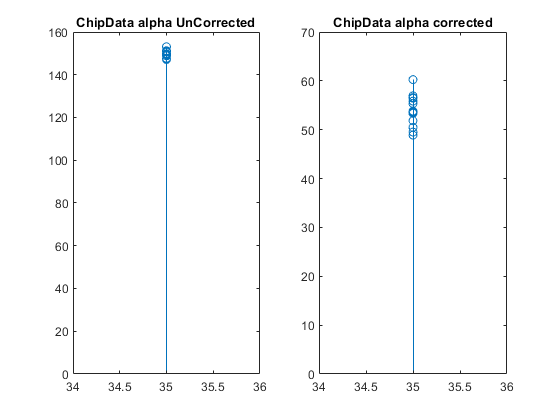

clear;
clc;
%load('alphaData.mat');
%load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaUNCorrected\alphaUNCorrected.mat')
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaUNCorrected\alphaUNCorrected_4X_MAC155_SUB_120.mat')


%8-Bit Weights
%load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols_4X_SUB.mat')


figure();
subplot(1,2,1)
dataDL=adc_VPVN;
dataDLMAcs=120+(reshape(dataDL,88,4,[])/0.9)*40;%MACs
MSB_powers=2.^[1 0 -1 -2];MSB_powers(1)=-MSB_powers(1);MSB_powers(2)=0;
LSB_powers=2.^[-3 -4 -5 -6];
powerCombs=cat(3,repmat(MSB_powers,72,1,size(dataCols,1)),repmat(LSB_powers,72,1,size(dataCols,1)));
arrDL=[[1:18],8+[19:54],16+[55:72]];dataDLMAcs=dataDLMAcs(arrDL,:,:);
dataDLMAcs=dataDLMAcs.*powerCombs;
dataDLMAcs=sum(dataDLMAcs,2);
dataDLMAcs=reshape(dataDLMAcs,72,size(dataCols,1),2);
dataDLMAcs=sum(dataDLMAcs,3);
dataDLMAcs=dataDLMAcs';
x_array = sum(dataCols,2)-sum(refCols,2);
stem(x_array ,-dataDLMAcs(:,1));

title('ChipData alpha UnCorrected');


%load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaCorrected\alphaCorrected.mat')
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaCorrected\alphaCorrected_4X_MAC155_SUB_120.mat')
subplot(1,2,2)
%8-Bit Weights
%load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols_4X_SUB.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaCorrected\dataWeights.mat');
%figure();
dataDL=adc_VPVN;
dataDLMAcs=(reshape(dataDL,88,4,[])/0.9)*40;%MACs
refEvaluate=120*ones(1,8);

MSB_powers=2.^[1 0 -1 -2];MSB_powers(1)=-MSB_powers(1);%MSB_powers(2)=0;
LSB_powers=2.^[-3 -4 -5 -6];
powerCombs=cat(3,repmat(MSB_powers,72,1,size(dataCols,1)),repmat(LSB_powers,72,1,size(dataCols,1)));
arrDL=[[1:18],8+[19:54],16+[55:72]];dataDLMAcs=dataDLMAcs(arrDL,:,:);
% for i=1:8
%     refEvaluate(i)=refCols(:,1:1024)*dataWeights(:,:,i);
%     dataDLMAcs(:,:,i)=dataDLMAcs(:,:,i)+refEvaluate(i);
% end

dataDLMAcs=dataDLMAcs.*powerCombs;
dataDLMAcs=sum(dataDLMAcs,2);
dataDLMAcs=reshape(dataDLMAcs,72,size(dataCols,1),2);
dataDLMAcs=sum(dataDLMAcs,3);
dataDLMAcs=dataDLMAcs';
x_array = sum(dataCols,2)-sum(refCols,2);
stem(x_array ,-dataDLMAcs(:,1));

title('ChipData alpha corrected');


load('origAlphaData.mat')
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaUNCorrected\dataWeights.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols_4X_SUB.mat');
wtX=zeros(15,72,8);
alpha_DLs=[alpha_DLs;zeros(1092-1024,72)];
wtSMACs=[]


wtSMACs =

     []



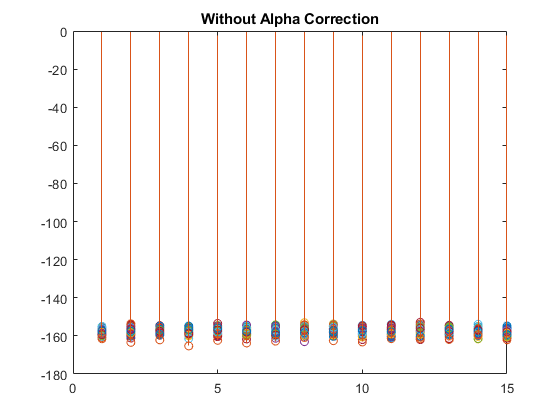

for wt_MSBbits=0:1
    for colSel=0:3        
        data_DL =zeros(1092,88);
        data_DL  = [dataWeights(:,:,colSel+1+4*(wt_MSBbits));zeros(1092-1024,88)];
        data_DL=data_DL(:,arrDL);
        data_DL=data_DL.*alpha_DLs;
        if(wt_MSBbits==0)
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*MSB_powers(colSel+1);
        else
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*LSB_powers(colSel+1);
        end
         wtSMACs(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL;
    end
end
wtX=sum(wtX,3);
figure();
stem(wtX);
title('Without Alpha Correction')

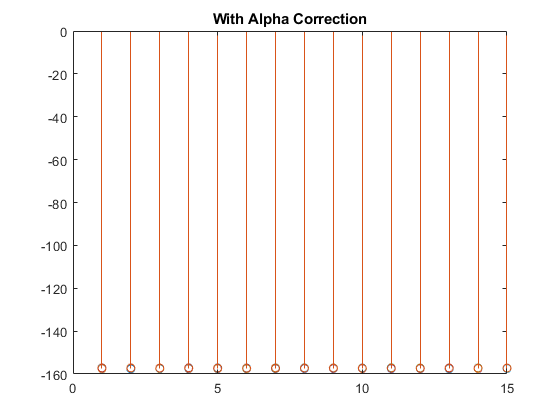


load('origAlphaData.mat')

load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataAlphaCorrected\dataWeights.mat')
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols_4X_SUB.mat');
wtX=zeros(15,72,8);
wtSVolt=zeros(15,72,8);
wtSMACs_alphaCorrected=[];
alpha_DLs=[alpha_DLs;zeros(1092-1024,72)];
for wt_MSBbits=0:1
    for colSel=0:3        
        data_DL =zeros(1092,88);
        data_DL  = [dataWeights(:,:,colSel+1+4*(wt_MSBbits));zeros(1092-1024,88)];
        data_DL=data_DL(:,arrDL);
        data_DL=data_DL.*alpha_DLs;
        if(wt_MSBbits==0)
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*MSB_powers(colSel+1);
        else
            wtX(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL*LSB_powers(colSel+1);
        end
        wtSMACs_alphaCorrected(:,:,colSel+1+4*(wt_MSBbits))=dataCols*data_DL;
    end
end
wtX_Final=sum(wtX,3);
figure();
stem(wtX_Final);
%figure();
powerS=repmat(reshape([MSB_powers,LSB_powers],1,1,[]),15,72,1);
%stem(sum(wtSVolt.*powerS,3));
title('With Alpha Correction')